# Find Friends of Friends in Social Neighborhood

This example shows how to search a social neighborhood to find the second-degree friends of a person, using the MATLAB® interface to Neo4j®. Assume that you have graph data that is stored on a Neo4j database which represents a social neighborhood. This database has seven nodes and eight relationships. Each node has only one unique property key `name` with a value ranging from `User1` through `User7`. Each relationship has type `knows`.

To find the second-degree friends of `User1`, use the MATLAB interface to Neo4j and the [digraph](docid:matlab_ref.bun70tf) object. For details about the MATLAB interface to Neo4j, see [Working with MATLAB Interface to Neo4j](docid:database_ug.bveys16-1).

The local machine hosts the Neo4j database with port number `7474`, user name `neo4j`, and password `matlab`. For a visual representation of the data in the database, see this figure.

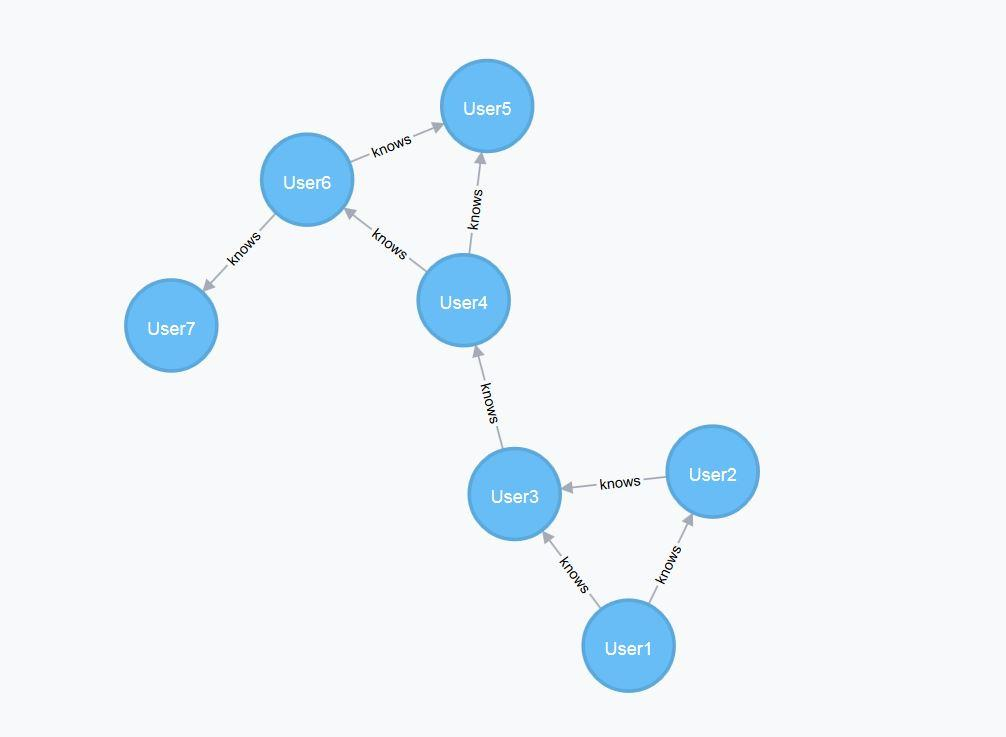

## Connect to Neo4j Database

Create a Neo4j connection object `neo4jconn` using the URL `http://localhost:7474/db/data`, user name `neo4j`, and password `matlab`.

url = 'http://localhost:7474/db/data';
username = 'neo4j';
password = 'matlab';

neo4jconn = neo4j(url,username,password);

Check the `Message` property of the Neo4j connection object `neo4jconn`. The blank `Message` property indicates a successful connection.

neo4jconn.Message

## Search for One Person in Database

Find the node that has the node label `Person` with the property name `User1`.

user1 = searchNode(neo4jconn,'Person','PropertyKey','name', ...
    'PropertyValue','User1')

## Search for All Second-Degree Friends of Person

Find outgoing relationships for `User1`. To limit the search to relationships with a distance of two or less, specify `2` as the value of the name-value pair argument `'Distance'`.

user1_relation = searchRelation(neo4jconn,user1,'out','Distance',2)

## Convert Graph Data to Directed Graph

Using the table `user1_relation.Nodes`, access the `name` property for each node that appears in the `NodeData` variable of the table.

Assign the table `user1_relation.Nodes` to `nodestable`. 

nodestable = user1_relation.Nodes

Assign the row names for each row in the table `nodestable` to `rownames`.

rownames = nodestable.Properties.RowNames

Access the `NodeData` variable from `nodestable` for each row. `nodedata` contains an array of structures.

nodedata = [nodestable.NodeData{rownames}]

To retrieve the `name` field from each structure, index into the array. `nodenames` is a cell array of character vectors that contains node names.

nodenames = {nodedata(:).name}

Create the `digraph` object `user1_graph` using the `neo4jStruct2Digraph` function with the relationship data stored in `user1_relation` and the node names stored in `nodenames`.

user1_graph = neo4jStruct2Digraph(user1_relation,'NodeNames',nodenames)

To see a visual representation of the graph, create a figure that displays `user1_graph`.

plot(user1_graph,'EdgeLabel',user1_graph.Edges.RelationType)

## Find Friends of Person

Retrieve a list of all the first-degree friends of `User1`. The `user1_friend` variable is a cell array of character vectors that contains the names of first-degree friends.

disp('Friends of User1 are:')
user1_friend = successors(user1_graph,'User1')

## Find Second-Degree Friends

To find the second-degree friends of `User1`, run `successors` again by looping through the list of the first-degree friends. `user1_friends_friend` is a cell array of character vectors that contains the names of second-degree friends.

user1_friends_friend = {};
for i = 1:length(user1_friend)
    user1_friends_friend = [user1_friends_friend; ...
        successors(user1_graph,user1_friend{i})]; 
end
disp('Friends of User1''s friends are:')
user1_friends_friend = unique(user1_friends_friend)

## Remove Duplicate Friends

Remove duplicates from the second-degree friends list that are already in the first-degree friends list using `setdiff`.

finalResult = setdiff(user1_friends_friend,user1_friend);

disp('User1''s second-degree friends are:')
for i = 1:length(finalResult)
    disp(finalResult{i})
end

`finalResult` is a cell array of character vectors that contains the names of second-degree friends. This list removes the names of the first-degree friends.

## Close Database Connection

close(neo4jconn)

*Copyright 2018 The MathWorks, Inc.*